# Test metabolic models

## Test human metabolic reconstruction base models

### See if metabolic models are capable of computing growth

First, we'll test the base human metabolic reconstructions to see if they output a feasible growth rate. If so, then we can add the epigenome-scale metabolic reactions to the model.

#### Human Metabolic Reconstruction 1

clear all;
initCobraToolbox; changeCobraSolver('gurobi', 'all')



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2020
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.25.4).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

ans = logical
   1


load model_human_duarte.mat
recon1 = metabolicmodel;

% Turn off reactions that negatively affect model performance.
posToTurnOff = find(ismember(recon1.rxns, {'ALR', 'MGSA', 'MGSA2'}));
recon1.ub(posToTurnOff) = 0; recon1.lb(posToTurnOff) = 0;

% Set growth rate to be from 0 to 1000
metabolicmodel.lb(3743) = 0;

% Solve using flux balance analysis
soln = optimizeCbModel(metabolicmodel);
grate = soln.x(3743)

grate = 1.1339

See which metabolites are encoded for the nucleus

nuclear_mets = findMetFromCompartment(metabolicmodel, '[c]')

nuclear_mets = 995×1 cell array
    {'10fthf5glu[c]'    }
    {'10fthf6glu[c]'    }
    {'10fthf7glu[c]'    }
    {'10fthf[c]'        }
    {'11-cis-retfa[c]'  }
    {'11docrtsl[c]'     }
    {'11docrtstrn[c]'   }
    {'12HPET[c]'        }
    {'12RHPET[c]'       }
    {'12ppd-R[c]'       }
    {'12ppd-S[c]'       }
    {'13-cis-oretn[c]'  }
    {'13-cis-retn[c]'   }
    {'13-cis-retnglc[c]'}
    {'13dampp[c]'       }
    {'13dpg[c]'         }
    {'15HPET[c]'        }
    {'17ahprgnlone[c]'  }
    {'17ahprgstrn[c]'   }
    {'1mncam[c]'        }
    {'1mpyr[c]'         }
    {'1pyr5c[c]'        }
    {'23doguln[c]'      }
    {'23dpg[c]'         }
    {'2425dhvitd2[c]'   }
    {'2425dhvitd3[c]'   }
    {'24nph[c]'         }
    {'25aics[c]'        }
    {'25hvitd2[c]'      }
    {'25hvitd3[c]'      }


nuclear_rxns = findRxnFromCompartment(metabolicmodel, '[c]')

nuclear_rxns = 2104×2 cell array
    {'10FTHF5GLUtl'  }    {'10fthf5glu[c]  -> 10fthf5glu[…'}
    {'10FTHF5GLUtm'  }    {'10fthf5glu[m]  -> 10fthf5glu[…'}
    {'10FTHF6GLUtl'  }    {'10fthf6glu[c]  -> 10fthf6glu[…'}
    {'10FTHF6GLUtm'  }    {'10fthf6glu[m]  -> 10fthf6glu[…'}
    {'10FTHF7GLUtl'  }    {'10fthf7glu[c]  -> 10fthf7glu[…'}
    {'10FTHF7GLUtm'  }    {'10fthf7glu[m]  -> 10fthf7glu[…'}
    {'10FTHFtl'      }    {'10fthf[c]  <=> 10fthf[l] '      }
    {'10FTHFtm'      }    {'10fthf[c]  <=> 10fthf[m] '      }
    {'11DOCRTSLtm'   }    {'11docrtsl[c]  <=> 11docrtsl[m] '}
    {'11DOCRTSLtr'   }    {'11docrtsl[c]  <=> 11docrtsl[r] '}
    {'11DOCRTSTRNtm' }    {'11docrtstrn[c]  <=> 11docrtst…'}
    {'11DOCRTSTRNtr' }    {'11docrtstrn[c]  <=> 11docrtst…'}
    {'13DAMPPOX'     }    {'13dampp[c] + h2o[c] + o2[c]  …'}
    {'1MNCAMti'      }    {'1mncam[c] + atp[c] + h2o[c]  …'}
    {'24NPHte'       }    {'24nph[e]  <=> 24nph[c] '        }
    {'24,25DHVITD2t' }    {'2425dhvitd2[c]  <=>

### Flux variability analysis for determining maximum and minimum fluxes

This code may be necessary to determine optimal upper and lower bounds based on the current network structure. Note that the run time is long if I run this at the genome-scale.

%initCobraToolbox
changeCobraSolver('gurobi', 'all');
optPercentage = 100;
osenseStr = 'max';
rxnNameList = 'biomass_objective';
%rxnNameList = [];
printLevel = 0;
allowLoops = false;
method = '2-norm';
[minFlux, maxFlux] = fluxVariability(recon1, ...
                                     optPercentage, osenseStr, ...
                                     rxnNameList, printLevel, ...
                                     allowLoops, method);

minFLux = 0

maxFlux = 1.1339

### Replace old metabolite identifiers using new BiGG annotation 

This version of RECON1 contains old BiGG identifier names. Let's replace these older names with new ones.

recon1 = metabolicmodel;
recon1.mets = strrep(recon1.mets, '[', '_');
recon1.mets = strrep(recon1.mets, ']', '');
recon1.rxns = strrep(recon1.rxns, '(', '_');
recon1.rxns = strrep(recon1.rxns, ')', '');
recon1.mets = regexprep(recon1.mets, '-L_', '__L_');
recon1.mets = regexprep(recon1.mets, '-D_', '__D_');

### Edit default substrate uptake rates to resemble minimal medium

Additionally, I will make sure that there is some influx of nutrients through exchange reactions, albeit the amount will be small as a default.

%load supplementary_software_code labels media_exchange1 mediareactions1 % list of nutrient conditions and uptake rates
%if contains(recon1.rxns, mediareactions1)
%    recon1.lb(contains(recon1.rxns, mediareactions1)) = -1.* media_exchange1;
%else
%    recon1.lb((contains(recon1.rxns, 'EX') & ~contains(recon1.rxns, mediareactions1))) = -0.005;
%end

## Add metabolic reactions associated with the epigenome-scale metabolic model

If the metabolic models have passed this base requirement, we can add the epigenomic reactions, which are available in the `metabolic_map.xlsx` spreadsheet. Note that the lysine methylation reactions are already encoded in RECON1, so if you don't want to read in the demand reactions (`{'DM_KMe1', 'DM_KMe2', 'DM_KMe3'}`), that's perfectly fine.

eGEM = recon1;

histoneReactionFile = 'metabolic_map.xlsx';
histoneReactionMap = readcell(histoneReactionFile, 'Sheet', 'Reactions');
histoneReactionMap(1, :) = [];

for i = 1:size(histoneReactionMap, 1)
    histoneReactionMap{i, 9} = fillmissing(string(histoneReactionMap(i, 9)), 'constant', "");
end

for i = 1:size(histoneReactionMap)
    rxnID = string(histoneReactionMap(i, 1));
    rxnName = histoneReactionMap(i, 2);
    rxnFormula = string(histoneReactionMap(i, 3));
    rev = histoneReactionMap(i, 4);
    ub = histoneReactionMap(i, 5);
    lb = histoneReactionMap(i, 6);
    %geneRule = histoneReactionMap(i, 8);
    %if contains(rxnID, {'DM_KAC', 'DM_KMe1', 'DM_KMe2', 'DM_KMe3', ...
    %                    'ACLYn', 'EX_peplys', 'PEPLYStn', 'OAAtn', 'CITtn', ...
    %                    'HISACYL', 'HISACYL', 'UACGAMtn', 'DM_HistAC', ...
    %                    'DM_HistGN', 'KACYLc', 'PDHn', ...
    %                    'PDHn', 'Actn', 'PYRtn', 'METATn', 'METtn', 'DM_HistMET'})
        eGEM = addReaction(eGEM, char(rxnID), ...
            'reactionName', char(rxnName), ...
            'reactionFormula', char(rxnFormula), ...
            'reversible', logical(rev{:}), ...
            'upperBound', ub{:}, ...
            'lowerBound', lb{:}, ...
            'checkDuplicate', true, ...
            'printLevel', 1);
    %else
    %end
end

LYSMTF1n	amet_n + peplys_n 	->	Nmelys_n + ahcys_n 
LYSMTF2n_B	2 amet_n + peplys_n 	->	Ndmelys_n + 2 ahcys_n 
LYSMTF3n_B	3 amet_n + peplys_n 	->	Ntmelys_n + 3 ahcys_n 


HISACYL	accoa_n + peplys_n 	->	coa_n + h_n + Naclys_n 
HISGLCN	peplys_n + uacgam_n 	->	udp_n + Nglclys_n 
UACGAMtn	uacgam_c 	<=>	uacgam_n 
DM_HistAC	accoa_n + Naclys_n 	->	
DM_HistMET	Ntmelys_n + amet_n 	->	
DM_HistGN	uacgam_n + Nglclys_n 	->	
KACYLc	accoa_c + peplys_c 	->	coa_c + h_c + Naclys_c 
EX_peplys	peplys_e 	<=>	peplys_c 


PEPLYStn	peplys_c 	<=>	peplys_n 
DM_KAC	Naclys_n 	->	
DM_KMe1	Nmelys_n 	->	
DM_KMe2	Ndmelys_n 	->	
DM_KMe3	Ntmelys_n 	->	
DM_KACcoa	coa_c + coa_n + Naclys_n + Naclys_c 	->	
ACLYn	atp_n + coa_n + cit_n 	->	accoa_n + adp_n + pi_n + oaa_n 
OAAtn	oaa_n 	<=>	oaa_c 
CITtn	cit_n 	<=>	cit_c 
DM_ACCOAn	accoa_n 	->	
DM_COAn	coa_n 	->	
DM_METn	met__L_n 	->	
DM_AMETn	amet_n 	->	
DM_AHCYSn	ahcys_n 	->	
DM_SUCCn	succ_n 	->	
DM_FUMn	fum_n 	->	
DM_CITn	cit_n 	->	
DM_AKGn	akg_n 	->	
DM_MALn	mal__L_n 	->	
DM_OAAn	oaa_n 	->	
DM_PYRn	pyr_n 	->	
DM_FOLn	fol_n 	->	
DM_ATPn	atp_n 	->	
DM_ADPn	adp_n 	->	
DM_NADn	nad_n 	->	
DM_NADHn	nadh_n 	->	
DM_ACn	ac_n 	->	
DM_GLNc	gln__L_c 	->	
DM_THRc	thr__L_c 	->	
DM_GLYBc	glyb_c 	->	
DM_CHOLc	chol_c 	->	
DM_AQCOBALc	aqcobal_c 	->	
METtn	met__L_c 	<=>	met__L_n 
SUCCtn	succ_c 	<=>	succ_n 
FUMtn	fum_c 	<=>	fum_n 
AKGtn	akg_c 	<=>	akg_n 
MALtn	mal__L_c 	<=>	mal__L_n 
PYRtn	pyr_c 	<=>	pyr_n 
Actn	ac_c 	<=>	ac_n 
FALDtn	fald_c 	<=>	fald_n 
METATn	atp_n + h2o_n + met__L_n 	->

### Test the epigenome-scale metabolic model

soln = optimizeCbModel(eGEM);
grate = soln.x(3743)

grate = 1.1339

%save('05042020eGEM1.mat', 'eGEM')

## Test behavior of the new epigenome-scale metabolic model with previous code from Shen et al., 2019

### Load variable space

This module compares the medium perturbation experiment between the new eGEM and the old acetylation model from Shen et al., 2019. First, we need to load some old variables from that paper, and the new eGEM in development.

%load 05042020eGEM.mat

% Old software from Shen et al
load supplementary_software_code acetylation_model                      % contains old metabolic model
load supplementary_software_code labels media_exchange1 mediareactions1 % list of nutrient conditions and uptake rates

% Update IDs
acetylation_model.mets = strrep(acetylation_model.mets, '[', '_');
acetylation_model.mets = strrep(acetylation_model.mets, ']', '');
acetylation_model.rxns = strrep(acetylation_model.rxns, '(', '_');
acetylation_model.rxns = strrep(acetylation_model.rxns, ')', '');

mediareactions1 = strrep(mediareactions1, '(', '_');
mediareactions1 = strrep(mediareactions1, ')', '');

posgluc = find(ismember(acetylation_model.rxns, 'EX_glc_e'));           % glucose uptake reaction in recon1. 
rxnpos  = [find(ismember(acetylation_model.rxns,'EX_KAC'));];           % Acetylation reaction
rxnpos2  = find(ismember(eGEM.rxns, 'DM_KAC'));
objpos = find(ismember(acetylation_model.rxns, 'biomass_objective'));   % biomass objective
minfluxflag = 0;                                                        % no PFBA
epsilon_acetylation = 1E-3;

old_eGEM = acetylation_model;
new_eGEM = eGEM;

### Nutrient perturbation

Next, we're computing the growth rates and acetylation fluxes from the base model undergoing nutrient supplementation or deprivation (denoted by the `kappatype`).  

% Set metabolic model default params to be in minimal medium
%if contains(eGEM.rxns, mediareactions1)
%    eGEM.lb(contains(eGEM.rxns, mediareactions1)) = -1.* media_exchange1;
%end

for kappatype = 1:2
    if kappatype == 1
        kappa  = 10; 
    else 
        kappa = 0.01;
    end 

    for i = 1:50
        kappa1 = kappa;
        if (kappatype == 2) & (ismember(i,[2,3,5:19])) % trace elements
            kappa1 = kappa/100;
        elseif (kappatype == 1) & (ismember(i,[1;4]))  % glucose or glutamine
            kappa1 = 3;
        end
        model2_old = old_eGEM; model2_new = new_eGEM;
        
        % Medium perturbation
        [~, pos]  = ismember(mediareactions1(i), model2_old.rxns);
        model2_old.lb(pos) = -media_exchange1(i, 1) * kappa1;
        [~, pos]  = ismember(mediareactions1(i), model2_new.rxns);
        model2_new.lb(pos) = -media_exchange1(i, 1)*kappa1;
        
        % Growth rates
        [old_flux, old_grate] =  constrain_flux_regulation(model2_old,[], [], 0, 0, 0, [], [], minfluxflag);
        [new_flux, new_grate] =  constrain_flux_regulation(model2_new,[], [], 0, 0, 0, [], [], minfluxflag);

        str1 = ['media_change_growth_', num2str(kappatype), '(i, 1) = old_flux(objpos);'];
        str2 = ['media_change_growth_', num2str(kappatype), '(i, 1) = new_flux(objpos);'];
        if ~isempty(old_flux) & ~isnan(old_flux)
            eval(str1); eval(str2);
        end

        j = 1;
        % Acetylation flux
        model3_old = model2_old; model3_new = model2_new;
        model3_old.c(rxnpos) = epsilon_acetylation;
        model3_new.c(rxnpos2) = epsilon_acetylation;
        [old_acet, old_acet_grate] =  constrain_flux_regulation(model3_old, [], [], 0, 0, 0, [], [], minfluxflag);
        [new_acet, new_acet_grate] =  constrain_flux_regulation(model3_new, [], [], 0, 0, 0, [], [], minfluxflag);

        str1 = ['media_change_histone_acet_old_',num2str(kappatype),'(i, j) = old_acet(rxnpos);'];
        str2 = ['media_change_histone_acet_new_',num2str(kappatype),'(i, j) = new_acet(rxnpos2);'];
        if ~isempty(old_acet) & ~isnan(old_acet)
            eval(str1); eval(str2);
        end
    end
end

### Plot the acetylation flux from both models

Finally, we'll make some plots for the acetylation flux with the old model and the new model.

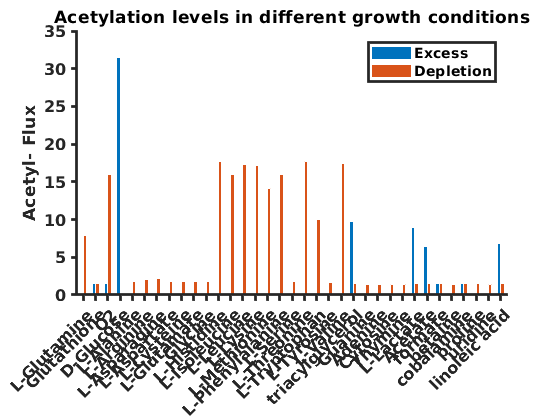

labels(2) = {'Glutathione'};
idx = [1:4,20:50];
figure;
bar([media_change_histone_acet_old_1(idx,1), media_change_histone_acet_old_2(idx,1) ], 1, 'edgecolor', 'w');
title('Acetylation levels in different growth conditions','fontweight','bold')
set(gca,'xtick',[1:length(mediareactions1(idx))],'xticklabel',labels(idx),'fontsize',8,'fontweight','bold','XTickLabelRotation',45)
set(gca,'TickDir', 'out')
set(gca,'box','off')
set(gca,'linewidth',2)
set(gcf,'color','white')
set(gca,'fontsize',12)
ylabel('Acetyl- Flux')
h = legend({'Excess','Depletion'});

figure;
bar([media_change_histone_acet_new_1(idx,1), media_change_histone_acet_new_2(idx,1) ], 1, 'edgecolor', 'w');
title('Acetylation levels in different growth conditions','fontweight','bold')
set(gca,'xtick',[1:length(mediareactions1(idx))], ...
        'xticklabel', labels(idx), ...
        'fontsize', 8, ...
        'fontweight', 'bold', ...
        'XTickLabelRotation', 45)
set(gca,'TickDir', 'out')
set(gca,'box','off')
set(gca,'linewidth',2)
set(gcf,'color','white')
set(gca,'fontsize',12)
ylabel('Acetyl- Flux')
h = legend({'Excess','Depletion'});

## Compute methylation from both models and plot it

First we need to add the methylation demand reactions to the acetylation model

% Add methylation demand reactions to acetylation model
for i = 1:size(histoneReactionMap)
    rxnID = string(histoneReactionMap(i, 1));
    rxnName = histoneReactionMap(i, 2);
    rxnFormula = string(histoneReactionMap(i, 3));
    rev = histoneReactionMap(i, 4);
    ub = histoneReactionMap(i, 5);
    lb = histoneReactionMap(i, 6);
    %geneRule = histoneReactionMap(i, 8);
    if contains(rxnID, {'DM_KMe1', 'DM_KMe2', 'DM_KMe3'})
        acetylation_model = addReaction(acetylation_model, char(rxnID), ...
            'reactionName', char(rxnName), ...
            'reactionFormula', char(rxnFormula), ...
            'reversible', logical(rev{:}), ...
            'upperBound', ub{:}, ...
            'lowerBound', lb{:}, ...
            'checkDuplicate', true, ...
            'printLevel', 1);
    else
        continue
    end
end

DM_KMe1	Nmelys_n 	->	
DM_KMe2	Ndmelys_n 	->	
DM_KMe3	Ntmelys_n 	->	


#### Medium perturbation for methylation

Next, let's repeat the medium perturbation analysis

% Methylation medium perturbation analysis
posgluc = find(ismember(acetylation_model.rxns, 'EX_glc_e'));           % glucose uptake reaction in recon1. 
objpos = find(ismember(acetylation_model.rxns, 'biomass_objective'));   % biomass objective
minfluxflag = 0;                                                        % no PFBA
epsilon_methylation = 1E-3;

old_eGEM = acetylation_model;
new_eGEM = eGEM;
methylation_reactions = ["DM_KMe1", "DM_KMe2", "DM_KMe3"];

for kappatype = 1:2
    if kappatype == 1
        kappa  = 10; 
    else 
        kappa = 0.01;
    end 
    
    for j = 1:length(methylation_reactions)
        rxnpos  = find(ismember(acetylation_model.rxns, methylation_reactions(j)));       
        rxnpos2  = find(ismember(eGEM.rxns, methylation_reactions(j)));           
        for i = 1:50
            kappa1 = kappa;
            if (kappatype == 2) & (ismember(i,[2,3,5:19])) % trace elements
                kappa1 = kappa/100;
            elseif (kappatype == 1) & (ismember(i,[1;4]))  % glucose or glutamine
                kappa1 = 3;
            end
            model2_old = old_eGEM; model2_new = new_eGEM;
            
            % Medium perturbation
            [~, pos]  = ismember(mediareactions1(i), model2_old.rxns);
            model2_old.lb(pos) = -media_exchange1(i, 1) * kappa1;
            [~, pos]  = ismember(mediareactions1(i), model2_new.rxns);
            model2_new.lb(pos) = -media_exchange1(i, 1)*kappa1;
            
            % Growth rates
            [old_flux, old_grate] =  constrain_flux_regulation(model2_old,[], [], 0, 0, 0, [], [], minfluxflag);
            [new_flux, new_grate] =  constrain_flux_regulation(model2_new,[], [], 0, 0, 0, [], [], minfluxflag);
    
            str1 = ['media_change_growth_', num2str(kappatype), '(i, 1) = old_flux(objpos);'];
            str2 = ['media_change_growth_', num2str(kappatype), '(i, 1) = new_flux(objpos);'];
            if ~isempty(old_flux) & ~isnan(old_flux)
                eval(str1); eval(str2);
            end
    
            % Acetylation flux
            model3_old = model2_old; model3_new = model2_new;
            model3_old.c(rxnpos) = epsilon_methylation;
            model3_new.c(rxnpos2) = epsilon_methylation;
            [old_methyl, old_methyl_grate] =  constrain_flux_regulation(model3_old, [], [], 0, 0, 0, [], [], minfluxflag);
            [new_methyl, new_methyl_grate] =  constrain_flux_regulation(model3_new, [], [], 0, 0, 0, [], [], minfluxflag);
    
            str1 = ['media_change_histone_methyl_old_',num2str(kappatype),'(i, j) = old_methyl(rxnpos);'];
            str2 = ['media_change_histone_methyl_new_',num2str(kappatype),'(i, j) = new_methyl(rxnpos2);'];
            if ~isempty(old_methyl) & ~isnan(old_methyl)
                eval(str1); eval(str2);
            end
        end
    end
end

#### Plot methylation medium perturbation

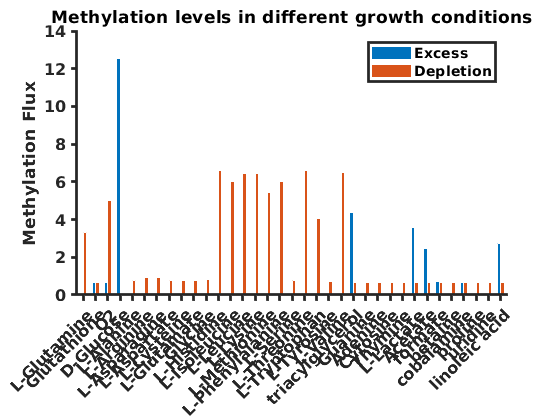

labels(2) = {'Glutathione'};
idx = [1:4,20:50];
figure;
bar([media_change_histone_methyl_old_1(idx,3), media_change_histone_methyl_old_2(idx,3) ], 1, 'edgecolor', 'w');
title('Methylation levels in different growth conditions','fontweight','bold')
set(gca,'xtick',[1:length(mediareactions1(idx))],'xticklabel',labels(idx),'fontsize',8,'fontweight','bold','XTickLabelRotation',45)
set(gca,'TickDir', 'out')
set(gca,'box','off')
set(gca,'linewidth',2)
set(gcf,'color','white')
set(gca,'fontsize',12)
ylabel('Methylation Flux')
h = legend({'Excess','Depletion'});

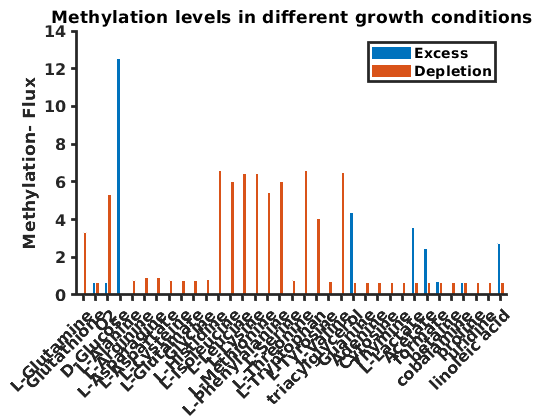

figure;
bar([media_change_histone_methyl_new_1(idx,3), media_change_histone_methyl_new_2(idx,3) ], 1, 'edgecolor', 'w');
title('Methylation levels in different growth conditions','fontweight','bold')
set(gca,'xtick',[1:length(mediareactions1(idx))], ...
        'xticklabel', labels(idx), ...
        'fontsize', 8, ...
        'fontweight', 'bold', ...
        'XTickLabelRotation', 45)
set(gca,'TickDir', 'out')
set(gca,'box','off')
set(gca,'linewidth',2)
set(gcf,'color','white')
set(gca,'fontsize',12)
ylabel('Methylation- Flux')
h = legend({'Excess','Depletion'});

## Human Metabolic Reconstruction 2

clear all;
initCobraToolbox; changeCobraSolver('gurobi', 'all')
load Recon2.v05.mat
recon2 = modelR205;

% Turn off reactions that negatively affect model performance.
posToTurnOff = find(ismember(recon2.rxns, {'ALR', 'MGSA', 'MGSA2'}));
recon2.ub(posToTurnOff) = 0; recon2.lb(posToTurnOff) = 0;
recon2.c(contains(recon2.rxns, 'biomass_reaction')) = 1

% Solve using flux balance analysis
soln = optimizeCbModel(recon2);
grate = soln.x(contains(recon2.rxns, 'biomass_reaction'))

### Replace old metabolite identifiers using new BiGG annotation 

This version of RECON1 contains old BiGG identifier names. Let's replace these older names with new ones.

recon2.mets = strrep(recon2.mets, '[', '_');
recon2.mets = strrep(recon2.mets, ']', '');
recon2.rxns = strrep(recon2.rxns, '(', '_');
recon2.rxns = strrep(recon2.rxns, ')', '');
recon2.mets = regexprep(recon2.mets, '-L_', '__L_');
recon2.mets = regexprep(recon2.mets, '-D_', '__D_');

## Add metabolic reactions associated with the epigenome-scale metabolic model

If the metabolic models have passed this base requirement, we can add the epigenomic reactions, which are available in the `metabolic_map.xlsx` spreadsheet. Note that the lysine methylation reactions are already encoded in RECON1, so if you don't want to read in the demand reactions (`{'DM_KMe1', 'DM_KMe2', 'DM_KMe3'}`), that's perfectly fine.

eGEM2 = recon2;

histoneReactionFile = 'metabolic_map.xlsx';
histoneReactionMap = readcell(histoneReactionFile, 'Sheet', 'Reactions');
histoneReactionMap(1, :) = [];

for i = 1:size(histoneReactionMap, 1)
    histoneReactionMap{i, 9} = fillmissing(string(histoneReactionMap(i, 9)), 'constant', "");
end

for i = 1:size(histoneReactionMap)
    rxnID = string(histoneReactionMap(i, 1));
    rxnName = histoneReactionMap(i, 2);
    rxnFormula = string(histoneReactionMap(i, 3));
    rev = histoneReactionMap(i, 4);
    ub = histoneReactionMap(i, 5);
    lb = histoneReactionMap(i, 6);
    eGEM2 = addReaction(eGEM2, char(rxnID), ...
        'reactionName', char(rxnName), ...
        'reactionFormula', char(rxnFormula), ...
        'reversible', logical(rev{:}), ...
        'upperBound', ub{:}, ...
        'lowerBound', lb{:}, ...
        'checkDuplicate', true, ...
        'printLevel', 1);
end

LYSMTF1n	amet_n + peplys_n 	->	ahcys_n + Nmelys_n 
LYSMTF2n_B	2 amet_n + peplys_n 	->	2 ahcys_n + Ndmelys_n 
LYSMTF3n_B	3 amet_n + peplys_n 	->	3 ahcys_n + Ntmelys_n 


HISACYL	accoa_n + peplys_n 	->	coa_n + h_n + Naclys_n 
HISGLCN	peplys_n + uacgam_n 	->	udp_n + Nglclys_n 
UACGAMtn	uacgam_c 	<=>	uacgam_n 
DM_HistAC	accoa_n + Naclys_n 	->	
DM_HistMET	amet_n + Ntmelys_n 	->	
DM_HistGN	uacgam_n + Nglclys_n 	->	
KACYLc	accoa_c + peplys_c 	->	h_c + coa_c + Naclys_c 
EX_peplys	peplys_e 	<=>	peplys_c 


PEPLYStn	peplys_c 	<=>	peplys_n 
DM_KAC	Naclys_n 	->	
DM_KMe1	Nmelys_n 	->	
DM_KMe2	Ndmelys_n 	->	
DM_KMe3	Ntmelys_n 	->	
DM_KACcoa	coa_c + coa_n + Naclys_n + Naclys_c 	->	
ACLYn	atp_n + coa_n + cit_n 	->	accoa_n + adp_n + pi_n + oaa_n 
OAAtn	oaa_n 	<=>	oaa_c 
CITtn	cit_n 	<=>	cit_c 
DM_ACCOAn	accoa_n 	->	
DM_COAn	coa_n 	->	
DM_METn	met__L_n 	->	
DM_AMETn	amet_n 	->	
DM_AHCYSn	ahcys_n 	->	
DM_SUCCn	succ_n 	->	
DM_FUMn	fum_n 	->	
DM_CITn	cit_n 	->	
DM_AKGn	akg_n 	->	
DM_MALn	mal__L_n 	->	
DM_OAAn	oaa_n 	->	
DM_PYRn	pyr_n 	->	
DM_FOLn	fol_n 	->	
DM_ATPn	atp_n 	->	
DM_ADPn	adp_n 	->	
DM_NADn	nad_n 	->	
DM_NADHn	nadh_n 	->	
DM_ACn	ac_n 	->	
DM_GLNc	gln__L_c 	->	
DM_THRc	thr__L_c 	->	
DM_GLYBc	glyb_c 	->	
DM_CHOLc	chol_c 	->	
DM_AQCOBALc	aqcobal_c 	->	
METtn	met__L_c 	<=>	met__L_n 
SUCCtn	succ_c 	<=>	succ_n 
FUMtn	fum_c 	<=>	fum_n 
AKGtn	akg_c 	<=>	akg_n 
MALtn	mal__L_c 	<=>	mal__L_n 
PYRtn	pyr_c 	<=>	pyr_n 
Actn	ac_c 	<=>	ac_n 
FALDtn	fald_c 	<=>	fald_n 
METATn	atp_n + h2o_n + met__L_n 	->

### Test the epigenome-scale metabolic model

soln = optimizeCbModel(eGEM2);
grate = soln.x(contains(eGEM2.rxns, 'biomass_reaction'))

grate = 3.1981

### Nutrient perturbation

Next, we're computing the growth rates and acetylation fluxes from the base model undergoing nutrient supplementation or deprivation (denoted by the `kappatype`).  

load supplementary_software_code acetylation_model                      % contains old metabolic model
load supplementary_software_code labels media_exchange1 mediareactions1 % list of nutrient conditions and uptake rates

% Update IDs
acetylation_model.mets = strrep(acetylation_model.mets, '[', '_');
acetylation_model.mets = strrep(acetylation_model.mets, ']', '');
acetylation_model.rxns = strrep(acetylation_model.rxns, '(', '_');
acetylation_model.rxns = strrep(acetylation_model.rxns, ')', '');

mediareactions1 = strrep(mediareactions1, '(', '_');
mediareactions1 = strrep(mediareactions1, ')', '');

posgluc = find(ismember(acetylation_model.rxns, 'EX_glc_e'));           % glucose uptake reaction in recon1. 
rxnpos  = [find(ismember(acetylation_model.rxns,'EX_KAC'));];           % Acetylation reaction
rxnpos2  = find(ismember(eGEM2.rxns, 'DM_KAC'));
objpos = find(ismember(acetylation_model.rxns, 'biomass_objective'));   % biomass objective
minfluxflag = 0;                                                        % no PFBA
epsilon_acetylation = 1E-3;

old_eGEM = acetylation_model;
new_eGEM = eGEM2;

### Nutrient perturbation

Next, we're computing the growth rates and acetylation fluxes from the base model undergoing nutrient supplementation or deprivation (denoted by the `kappatype`).  

% Set metabolic model default params to be in minimal medium
%if contains(eGEM.rxns, mediareactions1)
%    eGEM.lb(contains(eGEM.rxns, mediareactions1)) = -1.* media_exchange1;
%end

for kappatype = 1:2
    if kappatype == 1
        kappa  = 10; 
    else 
        kappa = 0.01;
    end 

    for i = 1:50
        kappa1 = kappa;
        if (kappatype == 2) & (ismember(i,[2,3,5:19])) % trace elements
            kappa1 = kappa/100;
        elseif (kappatype == 1) & (ismember(i,[1;4]))  % glucose or glutamine
            kappa1 = 3;
        end
        model2_old = old_eGEM; model2_new = new_eGEM;
        
        % Medium perturbation
        [~, pos]  = ismember(mediareactions1(i), model2_old.rxns);
        model2_old.lb(pos) = -media_exchange1(i, 1) * kappa1;
        [~, pos]  = ismember(mediareactions1(i), model2_new.rxns);
        model2_new.lb(pos) = -media_exchange1(i, 1)*kappa1;
        
        % Growth rates
        [old_flux, old_grate] =  constrain_flux_regulation(model2_old,[], [], 0, 0, 0, [], [], minfluxflag);
        [new_flux, new_grate] =  constrain_flux_regulation(model2_new,[], [], 0, 0, 0, [], [], minfluxflag);

        str1 = ['media_change_growth_', num2str(kappatype), '(i, 1) = old_flux(objpos);'];
        str2 = ['media_change_growth_', num2str(kappatype), '(i, 1) = new_flux(objpos);'];
        if ~isempty(old_flux) & ~isnan(old_flux)
            eval(str1); eval(str2);
        end

        j = 1;
        % Acetylation flux
        model3_old = model2_old; model3_new = model2_new;
        model3_old.c(rxnpos) = epsilon_acetylation;
        model3_new.c(rxnpos2) = epsilon_acetylation;
        [old_acet, old_acet_grate] =  constrain_flux_regulation(model3_old, [], [], 0, 0, 0, [], [], minfluxflag);
        [new_acet, new_acet_grate] =  constrain_flux_regulation(model3_new, [], [], 0, 0, 0, [], [], minfluxflag);

        str1 = ['media_change_histone_acet_old_',num2str(kappatype),'(i, j) = old_acet(rxnpos);'];
        str2 = ['media_change_histone_acet_new_',num2str(kappatype),'(i, j) = new_acet(rxnpos2);'];
        if ~isempty(old_acet) & ~isnan(old_acet)
            eval(str1); eval(str2);
        end
    end
end

### Plot the acetylation flux from both models

Finally, we'll make some plots for the acetylation flux with the old model and the new model.

labels(2) = {'Glutathione'};
idx = [1:4,20:50];
figure;
bar([media_change_histone_acet_old_1(idx,1), media_change_histone_acet_old_2(idx,1) ], 1, 'edgecolor', 'w');
title('Acetylation levels in different growth conditions','fontweight','bold')
set(gca,'xtick',[1:length(mediareactions1(idx))],'xticklabel',labels(idx),'fontsize',8,'fontweight','bold','XTickLabelRotation',45)
set(gca,'TickDir', 'out')
set(gca,'box','off')
set(gca,'linewidth',2)
set(gcf,'color','white')
set(gca,'fontsize',12)
ylabel('Acetyl- Flux')
h = legend({'Excess','Depletion'});

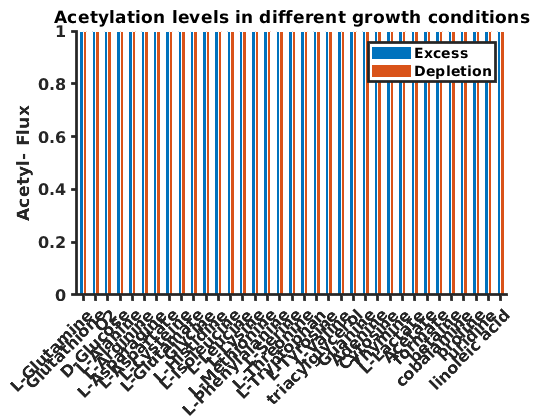

figure;
bar([media_change_histone_acet_new_1(idx,1), media_change_histone_acet_new_2(idx,1) ], 1, 'edgecolor', 'w');
title('Acetylation levels in different growth conditions','fontweight','bold')
set(gca,'xtick',[1:length(mediareactions1(idx))], ...
        'xticklabel', labels(idx), ...
        'fontsize', 8, ...
        'fontweight', 'bold', ...
        'XTickLabelRotation', 45)
set(gca,'TickDir', 'out')
set(gca,'box','off')
set(gca,'linewidth',2)
set(gcf,'color','white')
set(gca,'fontsize',12)
ylabel('Acetyl- Flux')
h = legend({'Excess','Depletion'});

## Human Metabolic Reconstruction 3

clear all;
initCobraToolbox; changeCobraSolver('gurobi', 'all')
load recon3.mat
recon3 = model;

% Turn off reactions that negatively affect model performance.
posToTurnOff = find(ismember(recon3.rxns, {'ALR', 'MGSA', 'MGSA2'}));
recon3.ub(posToTurnOff) = 0; recon3.lb(posToTurnOff) = 0;
recon3.c(ismember(recon3.rxns, 'BIOMASS_maintenance')) = 1;
recon3.lb(ismember(recon3.rxns, 'BIOMASS_maintenance_noTrTr')) = 0;
recon3.ub(ismember(recon3.rxns, 'BIOMASS_maintenance_noTrTr')) = 0;

% Solve using flux balance analysis
soln = optimizeCbModel(recon3);
grate = soln.x(ismember(recon3.rxns, 'BIOMASS_maintenance'));

### Replace old metabolite identifiers using new BiGG annotation 

This version of RECON1 contains old BiGG identifier names. Let's replace these older names with new ones.

recon3.mets = strrep(recon3.mets, '[', '_');
recon3.mets = strrep(recon3.mets, ']', '');
recon3.rxns = strrep(recon3.rxns, '(', '_');
recon3.rxns = strrep(recon3.rxns, ')', '');
recon3.mets = regexprep(recon3.mets, '-L_', '__L_');
recon3.mets = regexprep(recon3.mets, '-D_', '__D_');

## Add metabolic reactions associated with the epigenome-scale metabolic model

If the metabolic models have passed this base requirement, we can add the epigenomic reactions, which are available in the `metabolic_map.xlsx` spreadsheet. Note that the lysine methylation reactions are already encoded in RECON1, so if you don't want to read in the demand reactions (`{'DM_KMe1', 'DM_KMe2', 'DM_KMe3'}`), that's perfectly fine.

eGEM3 = recon3;

histoneReactionFile = 'metabolic_map.xlsx';
histoneReactionMap = readcell(histoneReactionFile, 'Sheet', 'Reactions');
histoneReactionMap(1, :) = [];

for i = 1:size(histoneReactionMap, 1)
    histoneReactionMap{i, 9} = fillmissing(string(histoneReactionMap(i, 9)), 'constant', "");
end

for i = 1:size(histoneReactionMap)
    rxnID = string(histoneReactionMap(i, 1));
    rxnName = histoneReactionMap(i, 2);
    rxnFormula = string(histoneReactionMap(i, 3));
    rev = histoneReactionMap(i, 4);
    ub = histoneReactionMap(i, 5);
    lb = histoneReactionMap(i, 6);
    eGEM3 = addReaction(eGEM3, char(rxnID), ...
        'reactionName', char(rxnName), ...
        'reactionFormula', char(rxnFormula), ...
        'reversible', logical(rev{:}), ...
        'upperBound', ub{:}, ...
        'lowerBound', lb{:}, ...
        'checkDuplicate', true, ...
        'printLevel', 1);
end

LYSMTF1n	amet_n + peplys_n 	->	Nmelys_n + ahcys_n 
LYSMTF2n_B	2 amet_n + peplys_n 	->	2 ahcys_n + Ndmelys_n 
LYSMTF3n_B	3 amet_n + peplys_n 	->	3 ahcys_n + Ntmelys_n 
LYSMTF2n_A	amet_n + Nmelys_n 	->	ahcys_n + Ndmelys_n 
LYSMTF3n_A	amet_n + Ndmelys_n 	->	ahcys_n + Ntmelys_n 
HISACYL	accoa_n + peplys_n 	->	coa_n + h_n + Naclys_n 
HISGLCN	peplys_n + uacgam_n 	->	udp_n + Nglclys_n 
UACGAMtn	uacgam_c 	<=>	uacgam_n 
DM_HistAC	accoa_n + Naclys_n 	->	
DM_HistMET	amet_n + Ntmelys_n 	->	
DM_HistGN	uacgam_n + Nglclys_n 	->	
KACYLc	accoa_c + peplys_c 	->	h_c + coa_c + Naclys_c 
EX_peplys	peplys_e 	<=>	peplys_c 
PEPLYStn	peplys_c 	<=>	peplys_n 
DM_KAC	Naclys_n 	->	
DM_KMe1	Nmelys_n 	->	
DM_KMe2	Ndmelys_n 	->	
DM_KMe3	Ntmelys_n 	->	
DM_KACcoa	coa_c + coa_n + Naclys_n + Naclys_c 	->	
ACLYn	atp_n + coa_n + cit_n 	->	accoa_n + adp_n + pi_n + oaa_n 
OAAtn	oaa_n 	<=>	oaa_c 
CITtn	cit_n 	<=>	cit_c 
DM_ACCOAn	accoa_n 	->	
DM_COAn	coa_n 	->	
DM_METn	met__L_n 	->	
DM_AMETn	amet_n 	->	
DM_AHCYSn	ahcys_n 	->	

DM_GLYBc	glyb_c 	->	


DM_AQCOBALc	aqcobal_c 	->	
METtn	met__L_c 	<=>	met__L_n 
SUCCtn	succ_c 	<=>	succ_n 
FUMtn	fum_c 	<=>	fum_n 
AKGtn	akg_c 	<=>	akg_n 
MALtn	mal__L_c 	<=>	mal__L_n 
PYRtn	pyr_c 	<=>	pyr_n 
Actn	ac_c 	<=>	ac_n 
FALDtn	fald_c 	<=>	fald_n 
METATn	atp_n + h2o_n + met__L_n 	->	ppi_n + pi_n + amet_n 
LSD_DML2n	h2o_n + o2_n + Ndmelys_n + fad_n 	->	h2o2_n + Nmelys_n + fald_n + fadh2_n 
LSD_DML1n	h2o_n + o2_n + fad_n + Nmmelys_n 	->	h2o2_n + peplys_n + fald_n + fadh2_n 
JMJ_DMT3n	o2_n + Ntmelys_n + akg_n + fe2_n 	->	Ndmelys_n + succ_n + fald_n + co2_n + fe3_n 
JMJ_DMT2n	o2_n + Ndmelys_n + akg_n + fe2_n 	->	Nmelys_n + succ_n + fald_n + co2_n + fe3_n 
JMJ_DMT1n	o2_n + Nmelys_n + akg_n + fe2_n 	->	peplys_n + succ_n + fald_n + co2_n + fe3_n 
ACSS2n	atp_n + coa_n + ac_n 	->	accoa_n + ppi_n + amp_n 
PDHn	coa_n + nad_n + pyr_n 	->	accoa_n + nadh_n + co2_n 
ADPtn	adp_n 	<=>	adp_c 


AMPtn	amp_n 	<=>	amp_c 


### Test the epigenome-scale metabolic model

soln = optimizeCbModel(eGEM3);
grate = soln.x(ismember(eGEM3.rxns, 'BIOMASS_maintenance'))

grate = 755.0032

### Nutrient perturbation

Next, we're computing the growth rates and acetylation fluxes from the base model undergoing nutrient supplementation or deprivation (denoted by the `kappatype`).  

load supplementary_software_code acetylation_model                      % contains old metabolic model
load supplementary_software_code labels media_exchange1 mediareactions1 % list of nutrient conditions and uptake rates

% Update IDs
acetylation_model.mets = strrep(acetylation_model.mets, '[', '_');
acetylation_model.mets = strrep(acetylation_model.mets, ']', '');
acetylation_model.rxns = strrep(acetylation_model.rxns, '(', '_');
acetylation_model.rxns = strrep(acetylation_model.rxns, ')', '');
acetylation_model.rxns = strrep(acetylation_model.rxns, '_L', '__L');
acetylation_model.rxns = strrep(acetylation_model.rxns, '_R', '__R');

mediareactions1 = strrep(mediareactions1, '(', '_');
mediareactions1 = strrep(mediareactions1, ')', '');
mediareactions1 = strrep(mediareactions1, '_L', '__L');
mediareactions1 = strrep(mediareactions1, '_R', '__R');

posgluc = find(ismember(acetylation_model.rxns, 'EX_glc_e'));           % glucose uptake reaction in recon1. 
rxnpos  = [find(ismember(acetylation_model.rxns,'EX_KAC'));];           % Acetylation reaction
rxnpos2  = find(ismember(eGEM3.rxns, 'DM_KAC'));
objpos = find(ismember(acetylation_model.rxns, 'biomass_objective'));   % biomass objective
minfluxflag = 0;                                                        % no PFBA
epsilon_acetylation = 1E-3;

old_eGEM = acetylation_model;
new_eGEM = eGEM3;

### Nutrient perturbation

Next, we're computing the growth rates and acetylation fluxes from the base model undergoing nutrient supplementation or deprivation (denoted by the `kappatype`).  

% Set metabolic model default params to be in minimal medium
%if contains(eGEM.rxns, mediareactions1)
%    eGEM.lb(contains(eGEM.rxns, mediareactions1)) = -1.* media_exchange1;
%end

for kappatype = 1:2
    if kappatype == 1
        kappa  = 10; 
    else 
        kappa = 0.01;
    end 

    for i = 1:50
        kappa1 = kappa;
        if (kappatype == 2) & (ismember(i,[2,3,5:19])) % trace elements
            kappa1 = kappa/100;
        elseif (kappatype == 1) & (ismember(i,[1;4]))  % glucose or glutamine
            kappa1 = 3;
        end
        model2_old = old_eGEM; model2_new = new_eGEM;
        
        % Medium perturbation
        [~, pos]  = ismember(mediareactions1(i), model2_old.rxns);
        model2_old.lb(pos) = -media_exchange1(i, 1) * kappa1;
        if ismember(mediareactions1(i), 'EX_glc_e')
            [~, pos]  = ismember('EX_glc__D_e', model2_new.rxns);
        elseif ismember(mediareactions1(i), 'EX_cl_e')
            continue
        elseif ismember(mediareactions1(i), 'EX_ca2_e')
            continue
        else
            [~, pos]  = ismember(mediareactions1(i), model2_new.rxns);
        end
        model2_new.lb(pos) = -media_exchange1(i, 1)*kappa1;
        
        % Growth rates
        [old_flux, old_grate] =  constrain_flux_regulation(model2_old,[], [], 0, 0, 0, [], [], minfluxflag);
        [new_flux, new_grate] =  constrain_flux_regulation(model2_new,[], [], 0, 0, 0, [], [], minfluxflag);

        str1 = ['media_change_growth_', num2str(kappatype), '(i, 1) = old_flux(objpos);'];
        str2 = ['media_change_growth_', num2str(kappatype), '(i, 1) = new_flux(objpos);'];
        if ~isempty(old_flux) & ~isnan(old_flux)
            eval(str1); eval(str2);
        end

        j = 1;
        % Acetylation flux
        model3_old = model2_old; model3_new = model2_new;
        model3_old.c(rxnpos) = epsilon_acetylation;
        model3_new.c(rxnpos2) = epsilon_acetylation;
        [old_acet, old_acet_grate] =  constrain_flux_regulation(model3_old, [], [], 0, 0, 0, [], [], minfluxflag);
        [new_acet, new_acet_grate] =  constrain_flux_regulation(model3_new, [], [], 0, 0, 0, [], [], minfluxflag);

        str1 = ['media_change_histone_acet_old_',num2str(kappatype),'(i, j) = old_acet(rxnpos);'];
        str2 = ['media_change_histone_acet_new_',num2str(kappatype),'(i, j) = new_acet(rxnpos2);'];
        if ~isempty(old_acet) & ~isnan(old_acet)
            eval(str1); eval(str2);
        end
    end
end

### Plot the acetylation flux from both models

Finally, we'll make some plots for the acetylation flux with the old model and the new model.

labels(2) = {'Glutathione'};
idx = [1:4,20:50];
figure;
bar([media_change_histone_acet_old_1(idx,1), media_change_histone_acet_old_2(idx,1) ], 1, 'edgecolor', 'w');
title('Acetylation levels in different growth conditions','fontweight','bold')
set(gca,'xtick',[1:length(mediareactions1(idx))],'xticklabel',labels(idx),'fontsize',8,'fontweight','bold','XTickLabelRotation',45)
set(gca,'TickDir', 'out')
set(gca,'box','off')
set(gca,'linewidth',2)
set(gcf,'color','white')
set(gca,'fontsize',12)
ylabel('Acetyl- Flux')
h = legend({'Excess','Depletion'});

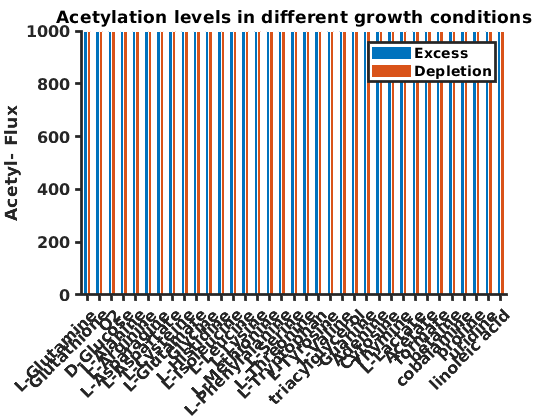

figure;
bar([media_change_histone_acet_new_1(idx,1), media_change_histone_acet_new_2(idx,1) ], 1, 'edgecolor', 'w');
title('Acetylation levels in different growth conditions','fontweight','bold')
set(gca,'xtick',[1:length(mediareactions1(idx))], ...
        'xticklabel', labels(idx), ...
        'fontsize', 8, ...
        'fontweight', 'bold', ...
        'XTickLabelRotation', 45)
set(gca,'TickDir', 'out')
set(gca,'box','off')
set(gca,'linewidth',2)
set(gcf,'color','white')
set(gca,'fontsize',12)
ylabel('Acetyl- Flux')
h = legend({'Excess','Depletion'});

## Human 1

clear all;
initCobraToolbox; changeCobraSolver('gurobi', 'all')
load Human1.mat

% Turn off reactions that negatively affect model performance.
posToTurnOff = find(ismember(ihuman.rxns, {'ALR', 'MGSA', 'MGSA2'}));
ihuman.ub(posToTurnOff) = 0; ihuman.lb(posToTurnOff) = 0;
ihuman.c(ismember(ihuman.rxns, 'biomass_human')) = 1;

% Solve using flux balance analysis
soln = optimizeCbModel(ihuman);
grate = soln.x(ismember(ihuman.rxns, 'biomass_human'))

### Replace old metabolite identifiers using new BiGG annotation 

This version of RECON1 contains old BiGG identifier names. Let's replace these older names with new ones.

recon3.mets = strrep(recon3.mets, '[', '_');
recon3.mets = strrep(recon3.mets, ']', '');
recon3.rxns = strrep(recon3.rxns, '(', '_');
recon3.rxns = strrep(recon3.rxns, ')', '');
recon3.mets = regexprep(recon3.mets, '-L_', '__L_');
recon3.mets = regexprep(recon3.mets, '-D_', '__D_');

## Add metabolic reactions associated with the epigenome-scale metabolic model

If the metabolic models have passed this base requirement, we can add the epigenomic reactions, which are available in the `metabolic_map.xlsx` spreadsheet. Note that the lysine methylation reactions are already encoded in RECON1, so if you don't want to read in the demand reactions (`{'DM_KMe1', 'DM_KMe2', 'DM_KMe3'}`), that's perfectly fine.

eGEM3 = recon3;

histoneReactionFile = 'metabolic_map.xlsx';
histoneReactionMap = readcell(histoneReactionFile, 'Sheet', 'Reactions');
histoneReactionMap(1, :) = [];

for i = 1:size(histoneReactionMap, 1)
    histoneReactionMap{i, 9} = fillmissing(string(histoneReactionMap(i, 9)), 'constant', "");
end

for i = 1:size(histoneReactionMap)
    rxnID = string(histoneReactionMap(i, 1));
    rxnName = histoneReactionMap(i, 2);
    rxnFormula = string(histoneReactionMap(i, 3));
    rev = histoneReactionMap(i, 4);
    ub = histoneReactionMap(i, 5);
    lb = histoneReactionMap(i, 6);
    eGEM3 = addReaction(eGEM3, char(rxnID), ...
        'reactionName', char(rxnName), ...
        'reactionFormula', char(rxnFormula), ...
        'reversible', logical(rev{:}), ...
        'upperBound', ub{:}, ...
        'lowerBound', lb{:}, ...
        'checkDuplicate', true, ...
        'printLevel', 1);
end

### Test the epigenome-scale metabolic model

soln = optimizeCbModel(eGEM3);
grate = soln.x(ismember(eGEM3.rxns, 'BIOMASS_maintenance'))

### Nutrient perturbation

Next, we're computing the growth rates and acetylation fluxes from the base model undergoing nutrient supplementation or deprivation (denoted by the `kappatype`).  

load supplementary_software_code acetylation_model                      % contains old metabolic model
load supplementary_software_code labels media_exchange1 mediareactions1 % list of nutrient conditions and uptake rates

% Update IDs
acetylation_model.mets = strrep(acetylation_model.mets, '[', '_');
acetylation_model.mets = strrep(acetylation_model.mets, ']', '');
acetylation_model.rxns = strrep(acetylation_model.rxns, '(', '_');
acetylation_model.rxns = strrep(acetylation_model.rxns, ')', '');
acetylation_model.rxns = strrep(acetylation_model.rxns, '_L', '__L');
acetylation_model.rxns = strrep(acetylation_model.rxns, '_R', '__R');

mediareactions1 = strrep(mediareactions1, '(', '_');
mediareactions1 = strrep(mediareactions1, ')', '');
mediareactions1 = strrep(mediareactions1, '_L', '__L');
mediareactions1 = strrep(mediareactions1, '_R', '__R');

posgluc = find(ismember(acetylation_model.rxns, 'EX_glc_e'));           % glucose uptake reaction in recon1. 
rxnpos  = [find(ismember(acetylation_model.rxns,'EX_KAC'));];           % Acetylation reaction
rxnpos2  = find(ismember(eGEM3.rxns, 'DM_KAC'));
objpos = find(ismember(acetylation_model.rxns, 'biomass_objective'));   % biomass objective
minfluxflag = 0;                                                        % no PFBA
epsilon_acetylation = 1E-3;

old_eGEM = acetylation_model;
new_eGEM = eGEM3;

### Nutrient perturbation

Next, we're computing the growth rates and acetylation fluxes from the base model undergoing nutrient supplementation or deprivation (denoted by the `kappatype`).  

% Set metabolic model default params to be in minimal medium
%if contains(eGEM.rxns, mediareactions1)
%    eGEM.lb(contains(eGEM.rxns, mediareactions1)) = -1.* media_exchange1;
%end

for kappatype = 1:2
    if kappatype == 1
        kappa  = 10; 
    else 
        kappa = 0.01;
    end 

    for i = 1:50
        kappa1 = kappa;
        if (kappatype == 2) & (ismember(i,[2,3,5:19])) % trace elements
            kappa1 = kappa/100;
        elseif (kappatype == 1) & (ismember(i,[1;4]))  % glucose or glutamine
            kappa1 = 3;
        end
        model2_old = old_eGEM; model2_new = new_eGEM;
        
        % Medium perturbation
        [~, pos]  = ismember(mediareactions1(i), model2_old.rxns);
        model2_old.lb(pos) = -media_exchange1(i, 1) * kappa1;
        if ismember(mediareactions1(i), 'EX_glc_e')
            [~, pos]  = ismember('EX_glc__D_e', model2_new.rxns);
        elseif ismember(mediareactions1(i), 'EX_cl_e')
            continue
        elseif ismember(mediareactions1(i), 'EX_ca2_e')
            continue
        else
            [~, pos]  = ismember(mediareactions1(i), model2_new.rxns);
        end
        model2_new.lb(pos) = -media_exchange1(i, 1)*kappa1;
        
        % Growth rates
        [old_flux, old_grate] =  constrain_flux_regulation(model2_old,[], [], 0, 0, 0, [], [], minfluxflag);
        [new_flux, new_grate] =  constrain_flux_regulation(model2_new,[], [], 0, 0, 0, [], [], minfluxflag);

        str1 = ['media_change_growth_', num2str(kappatype), '(i, 1) = old_flux(objpos);'];
        str2 = ['media_change_growth_', num2str(kappatype), '(i, 1) = new_flux(objpos);'];
        if ~isempty(old_flux) & ~isnan(old_flux)
            eval(str1); eval(str2);
        end

        j = 1;
        % Acetylation flux
        model3_old = model2_old; model3_new = model2_new;
        model3_old.c(rxnpos) = epsilon_acetylation;
        model3_new.c(rxnpos2) = epsilon_acetylation;
        [old_acet, old_acet_grate] =  constrain_flux_regulation(model3_old, [], [], 0, 0, 0, [], [], minfluxflag);
        [new_acet, new_acet_grate] =  constrain_flux_regulation(model3_new, [], [], 0, 0, 0, [], [], minfluxflag);

        str1 = ['media_change_histone_acet_old_',num2str(kappatype),'(i, j) = old_acet(rxnpos);'];
        str2 = ['media_change_histone_acet_new_',num2str(kappatype),'(i, j) = new_acet(rxnpos2);'];
        if ~isempty(old_acet) & ~isnan(old_acet)
            eval(str1); eval(str2);
        end
    end
end

### Plot the acetylation flux from both models

Finally, we'll make some plots for the acetylation flux with the old model and the new model.

labels(2) = {'Glutathione'};
idx = [1:4,20:50];
figure;
bar([media_change_histone_acet_old_1(idx,1), media_change_histone_acet_old_2(idx,1) ], 1, 'edgecolor', 'w');
title('Acetylation levels in different growth conditions','fontweight','bold')
set(gca,'xtick',[1:length(mediareactions1(idx))],'xticklabel',labels(idx),'fontsize',8,'fontweight','bold','XTickLabelRotation',45)
set(gca,'TickDir', 'out')
set(gca,'box','off')
set(gca,'linewidth',2)
set(gcf,'color','white')
set(gca,'fontsize',12)
ylabel('Acetyl- Flux')
h = legend({'Excess','Depletion'});
figure;
bar([media_change_histone_acet_new_1(idx,1), media_change_histone_acet_new_2(idx,1) ], 1, 'edgecolor', 'w');
title('Acetylation levels in different growth conditions','fontweight','bold')
set(gca,'xtick',[1:length(mediareactions1(idx))], ...
        'xticklabel', labels(idx), ...
        'fontsize', 8, ...
        'fontweight', 'bold', ...
        'XTickLabelRotation', 45)
set(gca,'TickDir', 'out')
set(gca,'box','off')
set(gca,'linewidth',2)
set(gcf,'color','white')
set(gca,'fontsize',12)
ylabel('Acetyl- Flux')
h = legend({'Excess','Depletion'});